Dm = 5.56 * 10^(-2); %アンテナ間隔 ≒波長/2
Lm = 500 * 1000; %距離 1000km
theta = pi * 3 / 6 ;
%dm = Dm * cos(theta);
freqHz = 2.675 * 10^9; %周波数
c = physconst('LightSpeed'); %光速
lambdam = c/freqHz; %波長
% for h=1:1:100
%     ht = h * 0.1; %0.1倍で0.1km刻みに
%     tandelta = atan(ht*1*1000 / Lm); %θ求める
%     theta = theta + tandelta;
%     dm = Dm * cos(theta); %距離
%     for i=1:100 %時間*10^11[s]
%         amplititude1 = 1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c))); %1個目の波
%         %amplititude2 = 1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c - (dm / c))));
%         sum = 0 ;
%         for j=1:399 %アンテナ399個増やす
%             amplititudefor=1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c) - (dm / c) * j)); %2個目以降の波
%             sum = amplititudefor + sum; 
%         end
%         sum = sum + amplititude1; %波足し合わせ
%         result(i) = sum;
%     end
%     max_result(h) = max(result); %波の最大
%     %plot(result)
% end


number_of_satel = struct('l',[1000 2000 3000 4000]); %円上の個数配列
%number_of_satel = struct('l',[10]);
Ans = 0;
h = 0;
max_result = zeros(1000,1);
cir_deg = pi /6;
parfor obser_y=1:1:800
    obser_y_2 = obser_y * 10000 *0.1
    res = zeros(200,1);
    for N = number_of_satel.l; %1円上の衛星数
        %Ans_per_1 = 0;
        R = Dm * N / (pi * 2); %円の半径?
        %R = sqrt( (Dm ^2) / (2 * (1 - cos(2 * pi / N)))); %円の半径
        for k = 1:N
            theta = 2 * pi * k / N;
            % theta_cir = atan(radius / Lm);
            %theta_for_circle = theta + theata_cir;
            % dm = Dm * cos(theta_cir);
            % amplititudefor=1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c) - (dm / c))) * j;
            % sum = amplititudefor + sum;
            x = R * cos(theta);
            y = R * sin(theta);
            z = 0;
            x_dash = x;
            y_dash = y * cos(cir_deg) + z * sin(cir_deg);
            z_dash = - y * sin(cir_deg) + z * cos(cir_deg) ;
            obser_x = 0;
            obser_z = Lm;
            hypotenuse = sqrt((obser_x - x_dash) ^ 2 + (obser_y_2 - y_dash) ^ 2 + (obser_z - z_dash) ^ 2);
            for i=1:200
                amplititudefor=cos(2 * pi * freqHz * (i*(1/(freqHz*200)) - (hypotenuse / c)));
                %sum = amplititudefor + sum;
                res(i) = res(i) + amplititudefor;
            end

            % Ans_temp = 1 + exp(1) ^ (-1 * 2 * pi * z_dash / lambdam);
            % Ans_per_1 = Ans_per_1 + Ans_temp;
            % Ans = Ans + Ans_per_1;
        end
        % h = h + 1;
        % max_result(h) = max(res);
    end
    max_result(obser_y) = max(res);
end
abs(Ans)

ans = 0

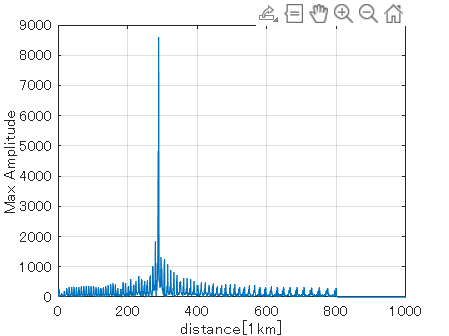

 
h=1:1:100;
% semilogy(h*0.1,max_result) %対数グラフ
plot(max_result)
grid on
xlabel("distance[1km]")
ylabel("Max Amplitude")


%plot(result)
